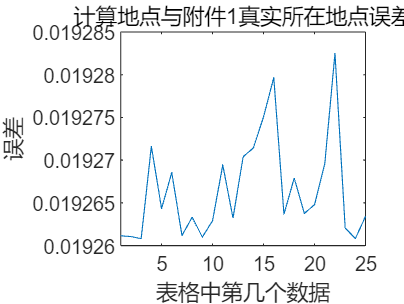

% a=all_var(:,4)';
error1=zeros(1,25);
error2=zeros(1,25);
error3=zeros(1,25);
for  i=1:length(a)
    if mod(i,2)==0
        error1(i/2)=c(i);
        error2(i/2)=a(i);
        error3(i/2)=b(i);
    end
end
s1=0;
s2=0;
s3=0;
for j=1:20
    s1=s1+all_l(j)/all_l(j+1)+abs(all_angle(j)+all_angle(j+1));
    s2=s2+all_l1(j)/all_l1(j+1)+abs(all_angle1(j)+all_angle1(j+1));
    s3=s3+all_l2(j)/all_l2(j+1)+abs(all_angle2(j)+all_angle2(j+1));
end
data1=sqrt(error1)./s1;
data2=sqrt(error2)./s2;
data3=sqrt(error3)./s3;

figure(1)
plot(1:25,data1)
title('计算地点与附件1真实所在地点误差')
xlim([1 25]);
xlabel('表格中第几个数据');
ylabel('误差')

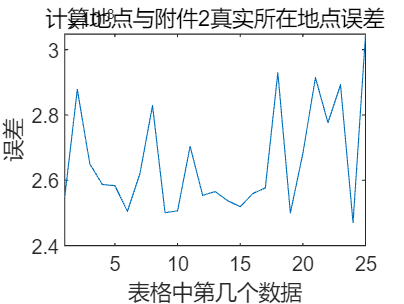

figure(2)
plot(1:25,data2)
title('计算地点与附件2真实所在地点误差')
xlim([1 25]);
xlabel('表格中第几个数据');
ylabel('误差')

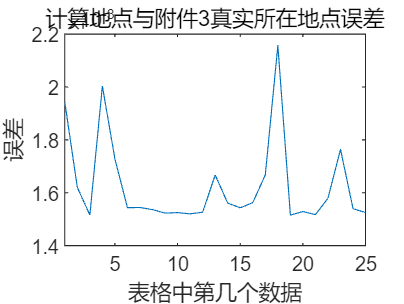

figure(3)
plot(1:25,data3)
title('计算地点与附件3真实所在地点误差')
xlim([1 25]);
xlabel('表格中第几个数据');
ylabel('误差')